## Stochastic traffic flow simulator example

This code calls the function CAtrafficFlowSimulator, which is a (very crude) traffic flow simulator that uses the so-called ASEP (asymmetric exclusion process) as the underlying model. The idea is that the 'road' is partitioned into a set of cells, each of which is occupied by exactly zero or one cars.

The agents are placed initially at random positions, and then at each time step, we employ a so-called shuffle update, which randomises their order. They then take it in turns to make a 'move'. Their 'move' constitutes checking the cell ahead, and if it is free, moving into it with probability p (a system parameter). This is then repeated many times and our goal is for a given value of that parameter p, find the density which maximises the traffic flow. 

The problem is that the simulator output has randomness in it, exaggerated by the fact that I have deliberately limited the number of timeSteps and road length spaceSteps that it is run for (to limit computational cost).

timeSteps = 10000;  % for each run, use just 100 time steps in 1st instance
spaceSteps = 100; % % use a road length of 100 cells, which loops round
p = 0.5; % the movement probability.
myFun = @(x)CAtrafficFlowSimulator(x,p,spaceSteps,timeSteps); 

myFun is the function to be minimised, the argument x is the density of agents in the simulation, ie the proportion of the cells that are occupied, which is between 0 and 1. The return value is the number of successful 'moves' during the simulation. We will try to find the 'x', ie the optimal density for traffic, which maximises traffic flow.

Scan over a range of densities

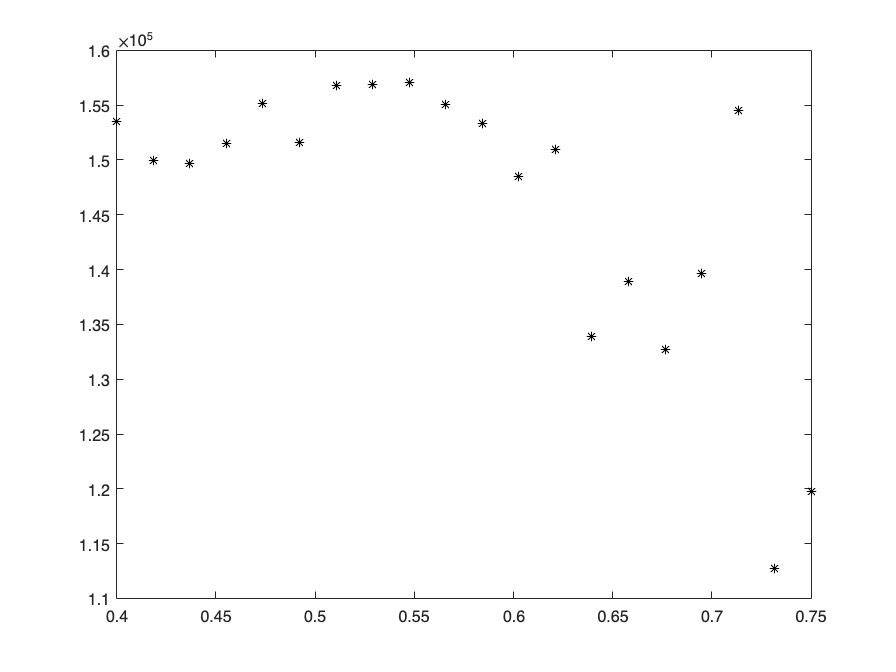

x=linspace(0.4,0.75,20); 
moveCount = 0*x; 
for i=1:length(x)
    moveCount(i)=myFun(x(i));
end
figure;
plot(x,moveCount,'k*')

disp('Total cost in timesteps ')

Total cost in timesteps 


length(x)*timeSteps

ans = 200000

Try running this section many times. You'll see the output is extremely variable.

You can of course repeat the simulation at each mesh point - to get an idea of the noise.

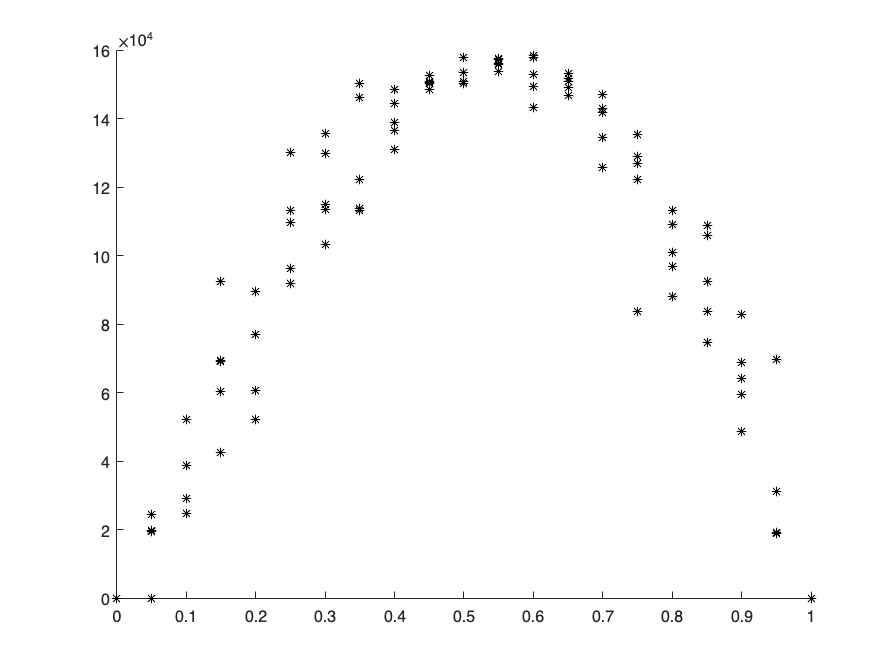

clear moveCount
x=[0:0.05:1];
figure; hold on
for k=1:5
for i=1:length(x)
    moveCount(i)=myFun(x(i));
end
plot(x,moveCount,'k*')
end

disp('Total cost in timesteps ')

Total cost in timesteps 


length(x)*timeSteps*k

ans = 1050000